#### USER DEFFINED SPATIAL FILTERING

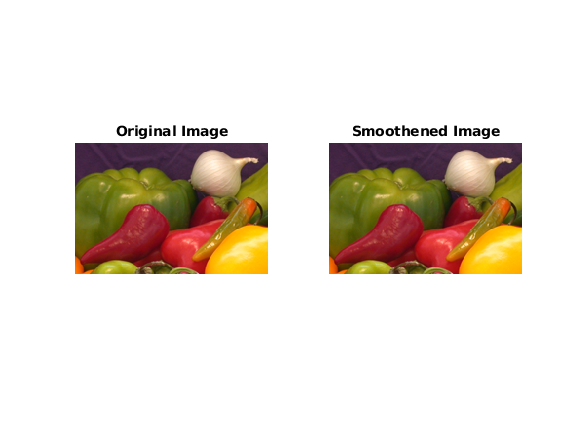

smooth('onion.png');

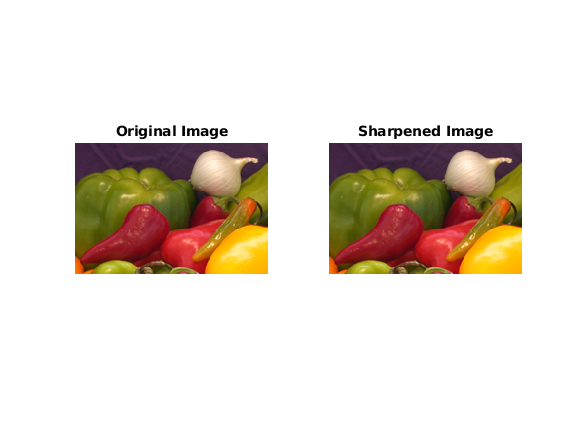

sharp('onion.png');

function outimg = smooth(inimg)
    [r,c]=size(inimg);
    a=[1 1 1; 1 1 1; 1 1 1];
    for x=1:r
        for y=1:c
            if(x==1|| y==1 || x==r || y==c)
                outimg(x,y)=inimg(x,y);
            else
                sum=0;
                for i=x-1:x+1
                    for j=y-1:y+1
                        u=i-x+2;
                        v=j-y+2;
                        sum=sum+inimg(i,j)*a(u,v);
                    end
                end
                outimg(x,y)=round(sum/9);
            end
        end
    end
    figure()
    subplot(1,2,1);imshow(inimg);title('Original Image');
    subplot(1,2,2);imshow(outimg);title('Smoothened Image');
end



%Sharpens the image using 3*3 filter
function outimg = sharp(inimg)
    [r,c]=size(inimg);
    a=[1 1 1; 1 -8 1; 1 1 1];
    for x=1:r
        for y=1:c
            if(x==1|| y==1 || x==r || y==c)
                outimg(x,y)=inimg(x,y);
            else
                sum=0;
                for i=x-1:x+1
                    for j=y-1:y+1
                        u=i-x+2;
                        v=j-y+2;
                        sum=sum+inimg(i,j)*a(u,v);
                    end
                end
                outimg(x,y)=round(sum);
                if (outimg(x,y)<0)
                    outimg(x,y)=0;
                elseif (outimg(x,y)>255)
                    outimg(x,y)=255;
                else
                    outimg(x,y)=outimg(x,y);
                end
            end
        end
    end
    figure()
    subplot(1,2,1);imshow(inimg);title('Original Image');
    subplot(1,2,2);imshow(outimg);title('Sharpened Image');
end